% Импортируйте данные из csv-файлов
close all
clear variables

starNames = importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
% Определите константы
lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c
nObs = size(spectra, 1);
nStars = size(starNames,1 );
% Определите диапазон длин волн
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;

lambda = (lambdaStart : lambdaDelta : lambdaEnd)';
% Рассчитайте скорости звезд относительно Земли
counter1 = 1

counter1 = 1

while counter1 < nStars + 1
    s = spectra(:, counter1);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    z = (lambdaHa / lambdaPr) - 1; % Если z > 0 -- красное смещение
    speed(counter1, 1) =  z * speedOfLight;
    counter1 = counter1 + 1;
end 
% Постройте график
movawayCounter = 0;
counter = 1

counter = 1

fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [441 379 560 420]
       Units: 'pixels'

  Show all properties


hold on
while counter < nStars + 1

s = spectra(:, counter)
[sHa, idx] = min(s);

lambdaHa = lambda(idx);   % Длина волны с минимальной интенсивностью


if ( speed(counter,1) > 0)
    plot(lambda, s, 'MarkerSize', 3, 'Color', [rand rand rand]);
    movawayCounter = movawayCounter + 1
    moveaway(movawayCounter, 1) = starNames(counter, 1)
    
end

if ( speed(counter,1) < 0)
    plot(lambda, s,'--', 'MarkerSize', 1, 'Color', [rand rand rand])
end

set(fg1, 'visible', 'on')

counter = counter + 1
end

s = 	1.0e+-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


counter = 2

s = 	1.0e+-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


counter = 3

s = 	1.0e+-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


counter = 4

s = 	1.0e+-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


movawayCounter = 1

moveaway = 1×1 cell array
    {'HD5211'}


counter = 5

s = 	1.0e+-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


movawayCounter = 2

moveaway = 2×1 cell array
    {'HD5211' }
    {'HD56030'}


counter = 6

s = 	1.0e+-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


movawayCounter = 3

moveaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


counter = 7

s = 	1.0e+-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


counter = 8

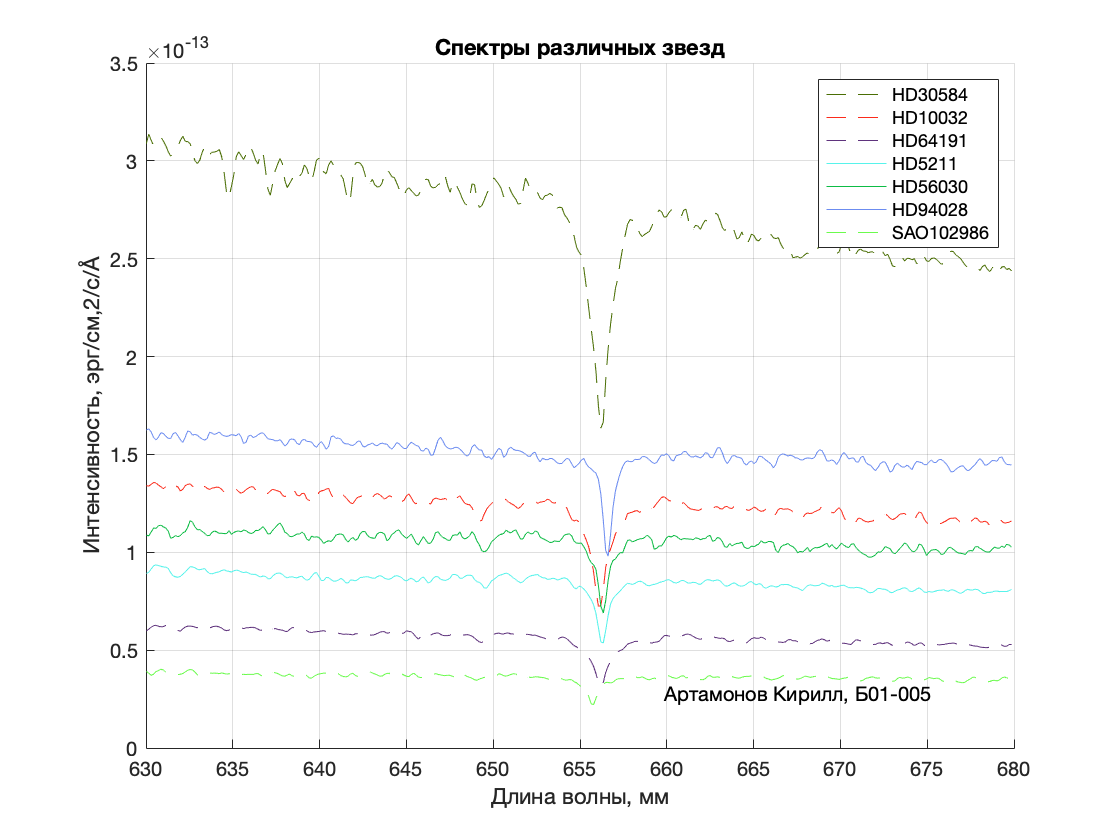

hold off
grid on

xlabel('Длина волны, мм')
ylabel(['Интенсивность, эрг/см,2/с/', char(197)])
title('Спектры различных звезд')
legend(starNames)
text(lambdaEnd - 20, max(s)*0.7, ['Артамонов Кирилл, Б01-005'])

% Сохраните график
%saveas(fg1, 'spectras.png')